% 第一题
%{ 
syms m r 
m = 128
r = 0:1:255
E = [0.5,1,2,5,10,20,50,100,500]
for e = E
    S = 1./(1+(m./r).^e)
    plot(S)
    hold on
end
legend('E=0.5','E=1','E=2','E=5','E=10', ...
    'E=20','E=50','E=100','E=500','location', 'best')
%}


% 第二题
%{
x = 0:1:7
pre = [0.17 0.25  0.21  0.16  0.07  0.08  0.04  0.02]
after = [0,0.17,0,0.25,0.21,0,0.23,0.14]
figure;
subplot(2,1,1)
bar(x, pre)
title("原直方图")
subplot(2,1,2)
bar(x, after)
title("均衡化所得直方图")
%}

% 第三题
figure;
img = im2gray(imread("Surtr.jpeg"))

img = 500×888 uint8 矩阵
   47   48   49   49   48   49   49   50   51   51   51   51   52   52   52   52   52   52   52   52   52   52   53   53   52   52   52   53   54   56   57   58   57   57   58   58   58   58   59   59   62   62   62   62   62   62   62   62   62   63
   47   48   49   49   49   49   50   50   51   51   51   51   52   52   52   52   52   52   52   52   52   52   52   53   53   53   53   54   55   56   57   57   57   57   58   58   58   59   59   59   61   62   62   62   62   62   62   62   63   63
   47   48   49   49   49   49   50   50   51   51   51   51   52   52   52   52   52   52   52   52   52   52   52   52   53   53   54   54   55   56   57   58   58   58   58   59   59   60   60   60   61   61   62   62   62   62   62   62   63   63
   47   48   49   49   49   49   50   50   51   51   51   51   52   52   52   52   53   52   52   52   52   52   52   52   53   53   55   56   57   58   59   59   59   59   59   60   60   61   61   61   62   62   62   62   6

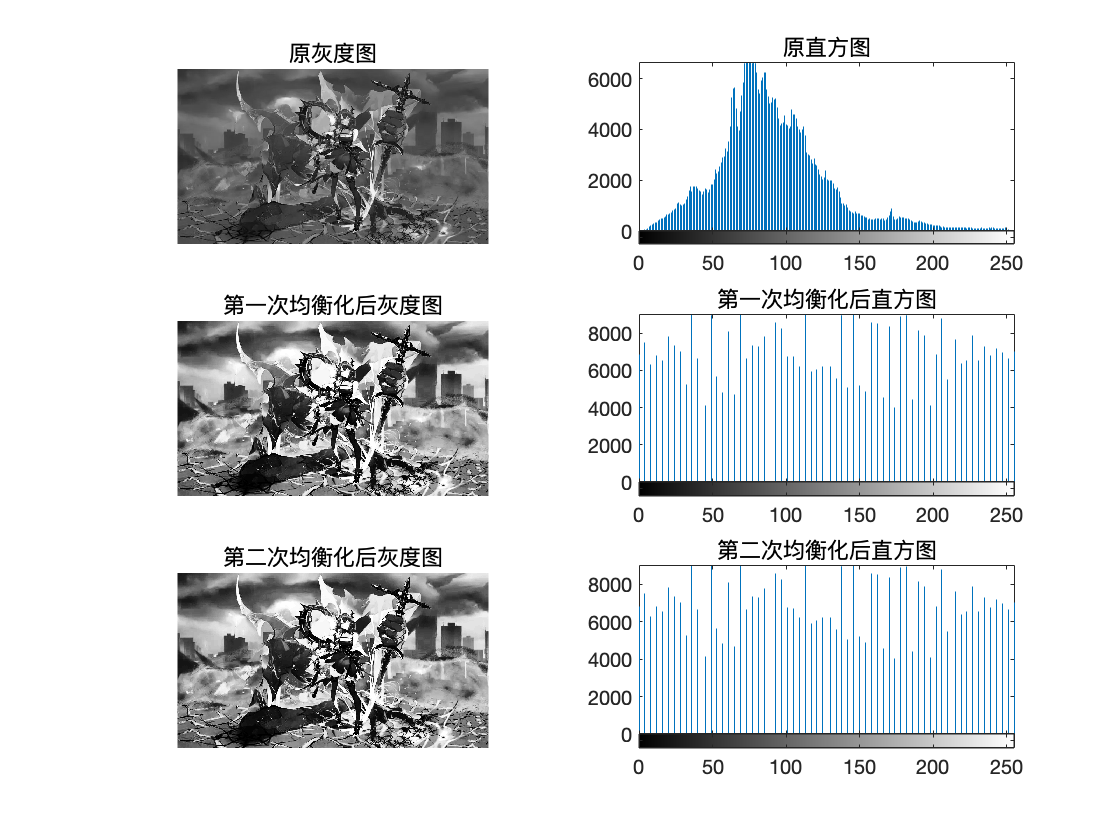

subplot(3,2,1)
imshow(img)
title("原灰度图")
subplot(3,2,2)
imhist(img)
title("原直方图")
%%  进行第一次均衡化
first_eq = histeq(img);
subplot(3,2,3)
imshow(first_eq)
title("第一次均衡化后灰度图")
subplot(3,2,4)
imhist(first_eq)
title("第一次均衡化后直方图")
%% 进行第二次均衡化
sec_eq = histeq(first_eq);
subplot(3,2,5)
imshow(sec_eq)
title("第二次均衡化后灰度图")
subplot(3,2,6)
imhist(sec_eq)
title("第二次均衡化后直方图")

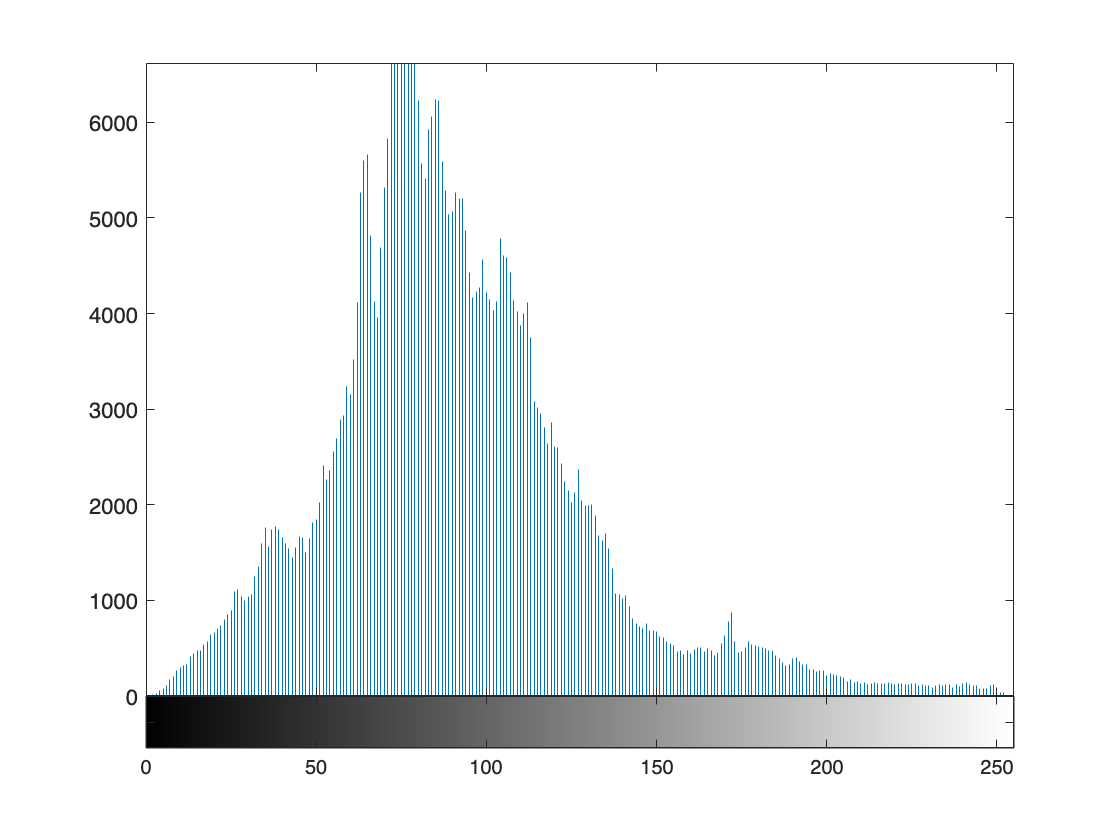


figure;
imhist(img)

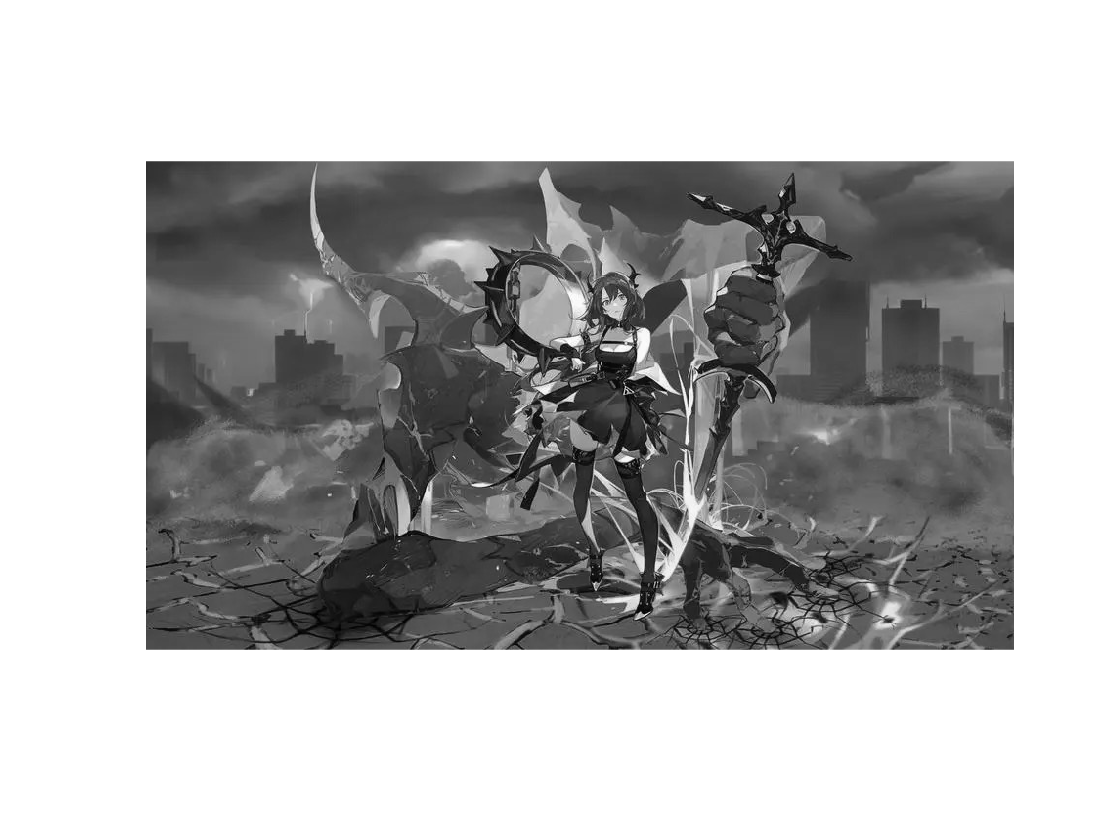

imshow(img)

syms m E
m = 128

m = 128

E = 10

E = 10

s = (255./(1+(m./double(img)).^E))

s =     0.0114    0.0140    0.0172    0.0172    0.0140    0.0172    0.0172    0.0211    0.0257    0.0257    0.0257    0.0257    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0378    0.0378    0.0312    0.0312    0.0312    0.0378    0.0455    0.0655    0.0782    0.0930    0.0782    0.0782    0.0930    0.0930    0.0930    0.0930    0.1104    0.1104    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.2126
    0.0114    0.0140    0.0172    0.0172    0.0172    0.0172    0.0211    0.0211    0.0257    0.0257    0.0257    0.0257    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0312    0.0378    0.0378    0.0378    0.0378    0.0455    0.0547    0.0655    0.0782    0.0782    0.0782    0.0782    0.0930    0.0930    0.0930    0.1104    0.1104    0.1104    0.1540    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.1812    0.2126    0

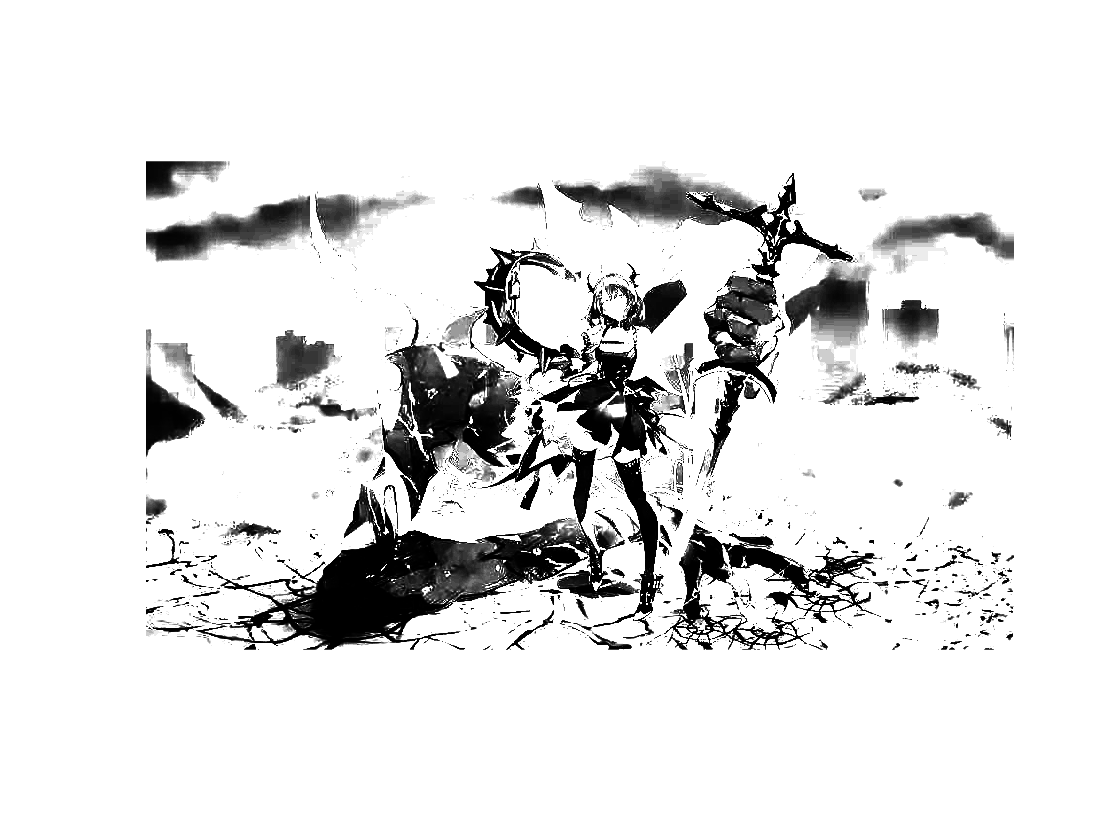

imshow(s)

r = 0:1:256

r =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


s = (255./(1+(m./r).^E))

s =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0006    0.0008    0.0010    0.0014    0.0018    0.0023    0.0029    0.0037    0.0047    0.0059    0.0074    0.0092    0.0114    0.0140    0.0172


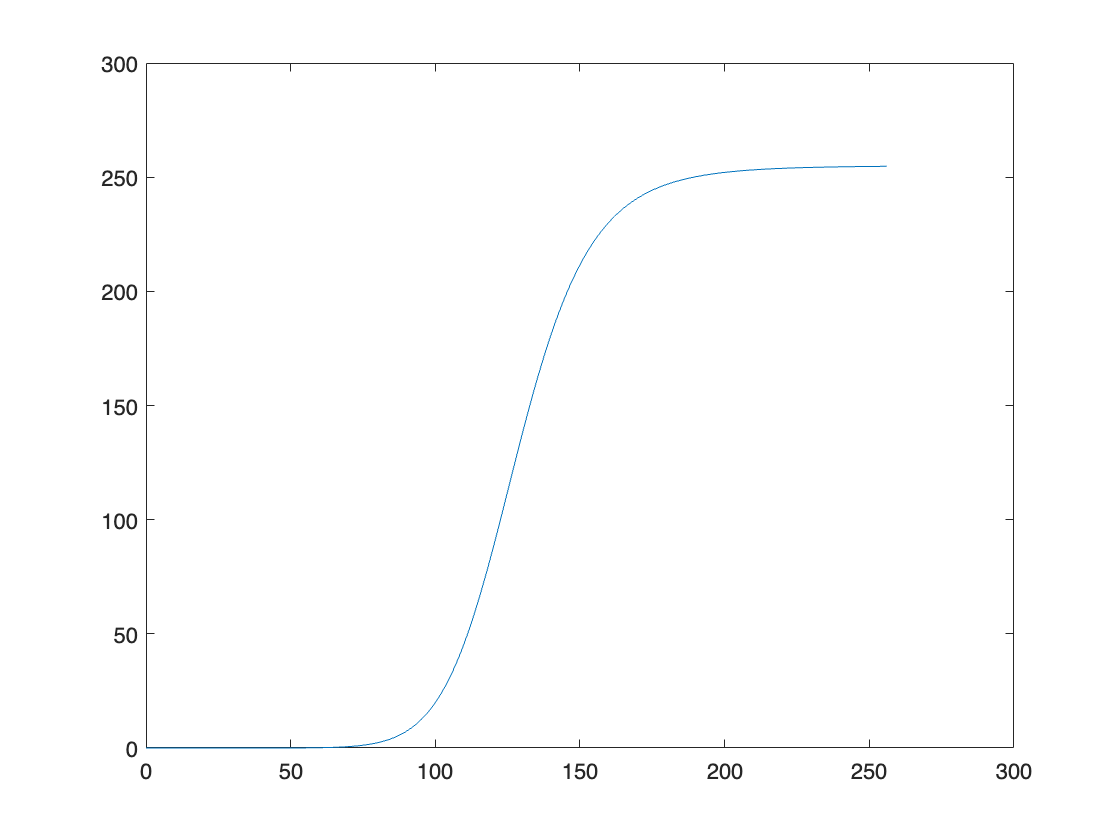

plot(r,s)


f = fft2(img)

f = 1.0e+07 *

   4.0361 + 0.0000i  -0.0588 + 0.0917i   0.0693 - 0.0194i  -0.0547 + 0.0062i  -0.0463 + 0.0827i   0.0208 - 0.0122i   0.0331 + 0.0892i  -0.0676 - 0.0318i   0.0486 + 0.0684i  -0.0139 + 0.0440i  -0.0612 + 0.0258i   0.0255 - 0.0211i  -0.0447 + 0.0103i   0.0334 + 0.0048i   0.0003 + 0.0594i   0.0071 - 0.0057i  -0.0035 + 0.0107i  -0.0137 - 0.0030i  -0.0282 + 0.0119i  -0.0020 - 0.0110i   0.0010 + 0.0235i   0.0100 + 0.0057i  -0.0021 - 0.0105i  -0.0173 + 0.0093i   0.0100 - 0.0045i  -0.0106 + 0.0121i   0.0091 + 0.0062i  -0.0074 + 0.0108i   0.0055 + 0.0023i  -0.0273 - 0.0057i   0.0245 + 0.0202i  -0.0079 - 0.0023i   0.0080 - 0.0023i  -0.0237 + 0.0122i   0.0034 + 0.0013i   0.0063 - 0.0135i  -0.0125 + 0.0212i   0.0151 - 0.0209i  -0.0046 + 0.0105i  -0.0012 + 0.0056i  -0.0138 + 0.0161i   0.0071 - 0.0073i   0.0030 + 0.0003i  -0.0084 + 0.0086i   0.0022 - 0.0074i  -0.0037 + 0.0061i  -0.0001 + 0.0119i   0.0016 - 0.0060i  -0.0001 - 0.0001i   0.0011 - 0.0001i
  -0.0918 - 0.1038i  -0.1600 + 0.1

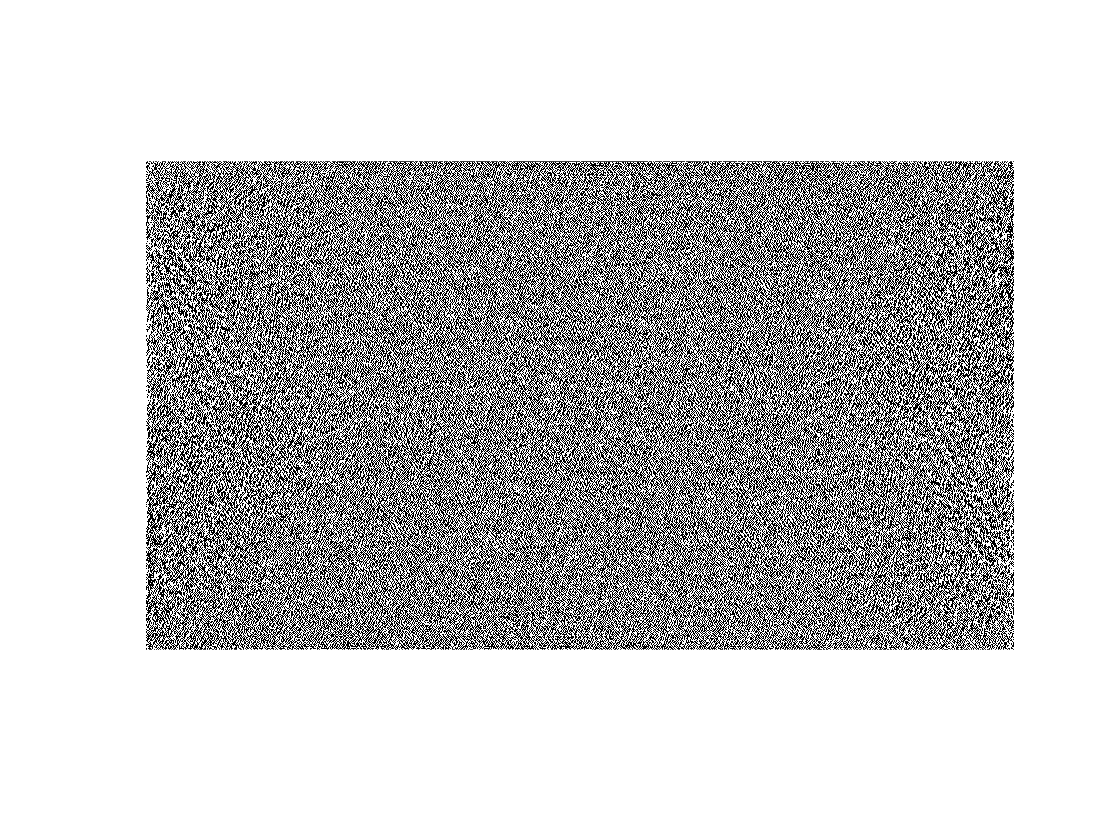

imshow(f)